# Hw9

## P1

aE = 149597898;
aJ = 778279959;
mu_S = 132712440017.99;
mu_E = 398600.4415;
mu_J = 126712767.8578;
aL = 384400;
mu_L = 4902.8005821478;
R_Earth = 6378.1363;
R_Lun = 1738.2;

rp = 190+R_Earth

rp = 6.5681e+03

r = aL

r = 384400

theta_ao = deg2rad(173.8);

e = (r-rp)/(rp-r*cos(theta_ao))

e = 0.9720

f = @(e) (r*(1+e*cos(theta_ao))-rp*(1+e));
fzero(f,0)

ans = 0.9720


p = rp*(1+e)

p = 1.2952e+04

a = p/(1-e^2)

a = 2.3450e+05

ra = p/(1-e)

ra = 4.6242e+05

period = 2*pi*sqrt(a^3/mu_E)

period = 1.1301e+06

epsilon = -mu_E/(2*a)

epsilon = -0.8499

(rp+ra)/2

ans = 2.3450e+05


E = acos(1/e-r/(a*e))

E = 2.2885

2*atan(tan(theta_ao/2)*sqrt((1-e)/(1+e)))

ans = 2.2885

rad2deg(E)

ans = 131.1236


t_tp = sqrt(a^3/mu_E)*(E-e*sin(E))

t_tp = 2.7992e+05

TOF = t_tp

TOF = 2.7992e+05

nL = sqrt(mu_E/aL^3)

nL = 2.6491e-06

phi = pi-nL*TOF

phi = 2.4001

rad2deg(phi)

ans = 137.5131

ro = aL;
vo = sqrt(2*mu_E/ro-mu_E/a)

vo = 0.6116

vL = sqrt(mu_E/aL)

vL = 1.0183

gamma_o = acos(sqrt(mu_E*p)/(ro*vo))

gamma_o = 1.2602

rad2deg(gamma_o)

ans = 72.2043


v_inf_L = sqrt(vo^2+vL^2-2*vo*vL*cos(gamma_o))

v_inf_L = 1.0150


ah = mu_L/v_inf_L^2

ah = 4.7585e+03


delta = 2*asin(vo/v_inf_L*sin(gamma_o))

delta = 1.2221

rad2deg(delta)

ans = 70.0187

eh = 1/(vo/v_inf_L*sin(gamma_o))

eh = 1.7430

1/sin(delta/2)

ans = 1.7430


rph = ah*(eh-1)

rph = 3.5358e+03

alt = rph-R_Lun

alt = 1.7976e+03


dOmega = theta_ao*2-2*pi

dOmega = -0.2164

rad2deg(dOmega)

ans = -12.4000


dv_eq = sqrt(2*v_inf_L^2*(1-cos(delta)))

dv_eq = 1.1647

alpha = pi-(pi-2*gamma_o)/2

alpha = 2.8310

rad2deg(alpha)

ans = 162.2043

Plot shit

figure
rot = theta_ao-pi/2

rot = 1.4626

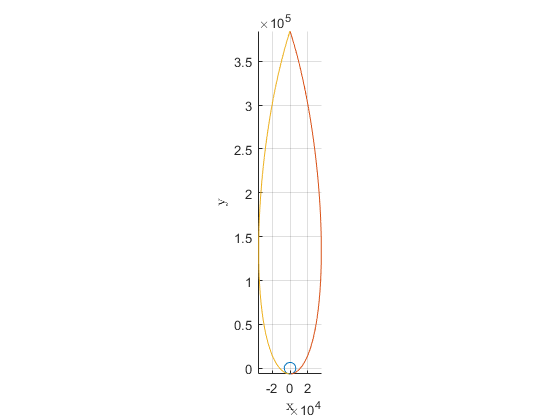

plot_orbit_3d(0,rp,0,0,0); %% parking orbit
plot_orbit_3d(e,a,0,0-rot,0, [0 theta_ao]); %% transfer orbit
plot_orbit_3d(e,a,0,dOmega-rot,0,[0 -theta_ao]); %% return orbit
view([0 0 1])

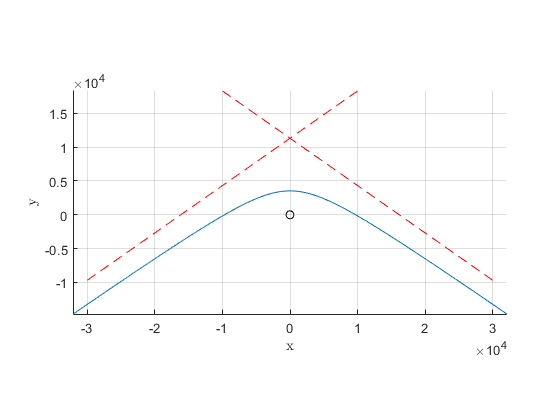


figure
plot_orbit_3d(eh,-ah,0,0+pi/2,0, [-2 2]);
plot(0,0,'ok')

x1 =[-3e4 1e4];
x2 =[-1e4 3e4];
f_asy1 = @(x) x*tan(delta/2)+ah+rp;
f_asy2 = @(x) x*tan(-delta/2)+ah+rp;

y1 = f_asy1(x1);
y2 = f_asy2(x2);
plot(x1,y1,'r--')
plot(x2,y2,'r--')
view([0 0 1])

## P2

EarthLaunch = 2453221;
FirstVenFlyby = 2454003;
FirstMerFlyby = 2454480;
MOI = 2455639;

TOF1 = FirstVenFlyby-EarthLaunch

TOF1 = 782

TOF2 = FirstMerFlyby-EarthLaunch

TOF2 = 1259

TOF3 = MOI-EarthLaunch

TOF3 = 2418

mu_M = 22032.080486418; % Mercury
aM = 57909101;
R_Mercury = 2439.7;

mu_V = 324858.59882646;
aV = 108207284;
R_Venus = 6051.9;

AU = aE;

rpT = 0.5*AU

rpT = 74798949

raT = AU;
aT = 0.5*(rpT+raT)

aT = 1.1220e+08

eT = 1-rpT/aT

eT = 0.3333

pT = aT*(1-eT^2)

pT = 99731932

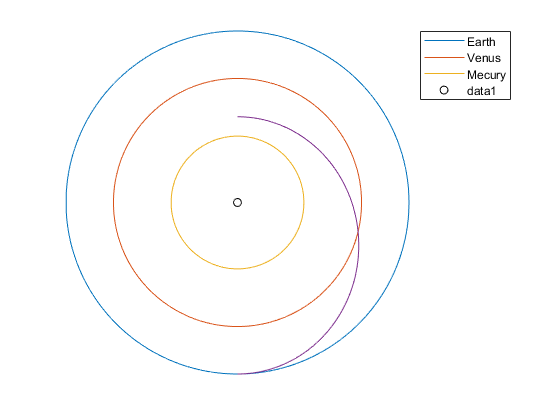


figure
plot_orbit_3d(0,aE,0,0,0);
plot_orbit_3d(0,aV,0,0,0);
plot_orbit_3d(0,aM,0,0,0);
plot_orbit_3d(eT,aT,0,pi/2,0,[0 -pi]);
legend('Earth','Venus','Mecury')
grid off
axis off
plot(0,0,'ok')
view([0 0 1])

theta_a_encounter = -acos(pT/(aV*eT)-1/eT)

theta_a_encounter = -1.8080

rad2deg(theta_a_encounter)

ans = -103.5902


periodT = 2*pi*sqrt(aT^3/mu_S)

periodT = 2.0498e+07


E_enc = 2*atan(tan(theta_a_encounter/2)*sqrt((1-eT)/(1+eT)))

E_enc = -1.4639

rad2deg(E_enc)

ans = -83.8739


t_tp = sqrt(aT^3/mu_S)*(E_enc-e*sin(E_enc))

t_tp = -1.6228e+06

TOF = 0.5*periodT+t_tp

TOF = 8.6260e+06

2990/R_Venus

ans = 0.4941

rph = R_Venus+2990

rph = 9.0419e+03


ro = aV;
vo = sqrt(2*mu_S/ro-mu_S/aT)

vo = 35.6384

vV = sqrt(mu_S/aV)

vV = 35.0209


gamma_o = -acos(sqrt(mu_S*pT)/(ro*vo))

gamma_o = -0.3380

rad2deg(gamma_o)

ans = -19.3683


v_inf_V = sqrt(vV^2+vo^2-2*vV*vo*cos(gamma_o))

v_inf_V = 11.9017


ah = mu_V/v_inf_V^2

ah = 2.2934e+03

eh = rph/ah+1

eh = 4.9426

delta = 2*asin(1/eh)

delta = 0.4075

rad2deg(delta)

ans = 23.3457


eta = asin(vo/v_inf_V*sin(abs(gamma_o)))

eta = 1.4529

rad2deg(eta)

ans = 83.2472


rho = asin(vV/v_inf_V*sin(abs(gamma_o)))

rho = 1.3506

rad2deg(rho)

ans = 77.3845


rho+eta+abs(gamma_o)

ans = 3.1416


dv_eq = sqrt(2*v_inf_V^2*(1-cos(delta)))

dv_eq = 4.8160

alpha = pi-rho+(pi-delta)/2

alpha = 3.1580

rad2deg(alpha)

ans = 180.9427


vn = sqrt(vV^2+v_inf_V^2-2*vV*v_inf_V*cos(eta-delta))

vn = 30.8231


gamma_n = -asin(v_inf_V/vn*sin(eta-delta))

gamma_n = -0.3406

rad2deg(gamma_n)

ans = -19.5156


sqrt(vo^2+vn^2-2*vo*vn*cos(abs(gamma_n)-abs(gamma_o)))

ans = 4.8160


rn = ro

rn = 108207284

en = sqrt((rn*vn^2/mu_S-1)^2*cos(gamma_n)^2+sin(gamma_n)^2)

en = 0.3959


theta_an = atan2(rn*vn^2/mu_S*cos(gamma_n)*sin(gamma_n),rn*vn^2/mu_S*cos(gamma_n)^2-1)

theta_an = -2.4778

rad2deg(theta_an)

ans = -141.9659


pn = rn*(1+en*cos(theta_an))

pn = 7.4467e+07

an = pn/(1-en^2)

an = 8.8306e+07

rpn = an*(1-en)

rpn = 5.3348e+07

ran = an*(1+en)

ran = 1.2326e+08

period_n = 2*pi*sqrt(an^3/mu_S)

period_n = 1.4312e+07

dOmega = theta_a_encounter-theta_an

dOmega = 0.6698

rad2deg(dOmega)

ans = 38.3758

Plot more shit

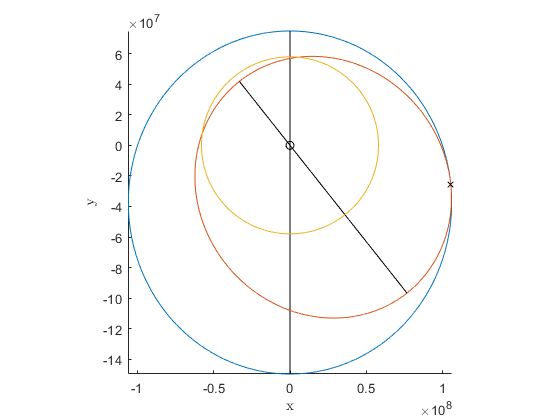

figure
plot_orbit_3d(eT,aT,0,0+pi/2,0,[0 2*pi],1);
plot_orbit_3d(en,an,0,dOmega+pi/2,0,[0 2*pi],1);
plot_orbit_3d(0,aM,0,0,0);
plot(0,0,'ok')
plot(rn*cos(theta_a_encounter+pi/2),rn*sin(theta_a_encounter+pi/2),'kx')
grid off
view([0 0 1])

## P3

R_Jupiter = 71492;
aR = 15*R_Jupiter

aR = 1072380

eR = 0.25;
R_Remus = 3000;
mu_R = 1e5;

rp = 7.5*R_Jupiter

rp = 536190

e = 0.5

e = 0.5000

a = rp/(1-e)

a = 1072380

pR = aR*(1-eR^2)

pR = 1.0054e+06

r = aR;
theta_a1 = acos(pR/(r*eR)-1/eR)

theta_a1 = 1.8235

rad2deg(theta_a1)

ans = 104.4775


p = a*(1-e^2)

p = 804285

theta_a2 = acos(p/(r*e)-1/e)

theta_a2 = 2.0944

rad2deg(theta_a2)

ans = 120.0000


dtheta = theta_a2-theta_a1

dtheta = 0.2709

rad2deg(dtheta)

ans = 15.5225


b = 2*atan(sqrt((1+e)/(1-e)))-2*atan(sqrt((1+eR)/(1-eR)))

b = 0.2709

rad2deg(b)

ans = 15.5225

plot shit

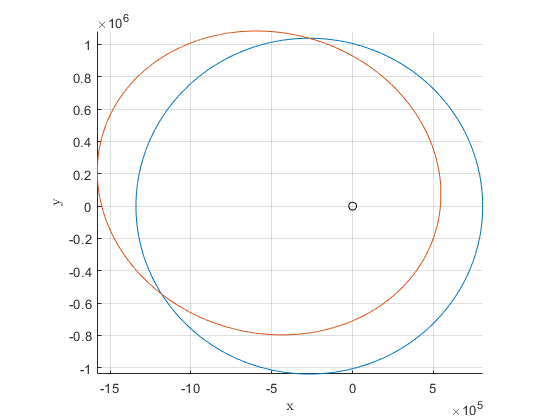

figure
plot_orbit_3d(eR,aR,0,0,0);
plot_orbit_3d(e,a,0,-dtheta,0);
plot(0,0,'ok')
view([0 0 1])

ro = aR

ro = 1072380

vo = sqrt(2*mu_J/ro-mu_J/a)

vo = 10.8702

gamma_o = acos(sqrt(mu_J*p)/(ro*vo))

gamma_o = 0.5236

rad2deg(gamma_o)

ans = 30.0000


vR = sqrt(2*mu_J/r-mu_J/aR)

vR = 10.8702

gamma_R = acos(sqrt(mu_J*pR)/(r*vR))

gamma_R = 0.2527

rad2deg(gamma_R)

ans = 14.4775

rph = R_Remus+1500

rph = 4500

v_inf_R = sqrt(vR^2+vo^2-2*vR*vo*cos(gamma_o-gamma_R))

v_inf_R = 2.9359


ah = mu_R/v_inf_R^2

ah = 1.1601e+04

eh = rph/ah+1

eh = 1.3879

delta = 2*asin(1/eh)

delta = 1.6091

rad2deg(delta)

ans = 92.1949


eta = asin(vo/v_inf_R*sin(gamma_o-gamma_R))

eta = 1.4353

rad2deg(eta)

ans = 82.2388


rho = asin(vR/v_inf_R*sin(gamma_o-gamma_R))

rho = 1.4353

rad2deg(rho)

ans = 82.2388


vn = sqrt(v_inf_R^2+vR^2-2*v_inf_R*vR*cos(delta-eta))

vn = 7.9946


gamma_n = gamma_R- asin(v_inf_R/vn*sin(delta-eta))

gamma_n = 0.1891

rad2deg(gamma_n)

ans = 10.8371


rn = ro

rn = 1072380

en = sqrt((rn*vn^2/mu_J-1)^2*cos(gamma_n)^2+sin(gamma_n)^2)

en = 0.4885


theta_an = atan2(rn*vn^2/mu_J*cos(gamma_n)*sin(gamma_n),rn*vn^2/mu_J*cos(gamma_n)^2-1)

theta_an = 2.9357

rad2deg(theta_an)

ans = 168.2022


pn = rn*(1+en*cos(theta_an))

pn = 5.5955e+05

an = pn/(1-en^2)

an = 7.3496e+05

rpn = an*(1-en)

rpn = 3.7590e+05

ran = an*(1+en)

ran = 1.0940e+06

period_n = 2*pi*sqrt(an^3/mu_J)

period_n = 3.5170e+05

dOmega = theta_a2-theta_an

dOmega = -0.8413

rad2deg(dOmega)

ans = -48.2022


epsilon_n = -mu_J/(2*an)

epsilon_n = -86.2037


dv_eq = sqrt(2*v_inf_R^2*(1-cos(delta)))

dv_eq = 4.2308


alpha = pi+rho-(pi-delta)/2

alpha = 3.8107

rad2deg(alpha)

ans = 218.3362


dv_eq_vnb = dv_eq*[cos(alpha) 0 sin(alpha)]

dv_eq_vnb =    -3.3186         0   -2.6243


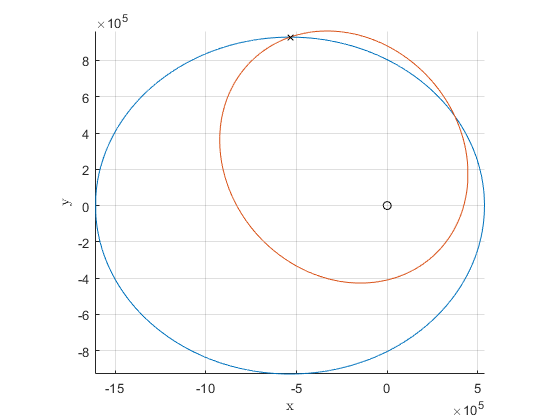

figure
plot_orbit_3d(e,a,0,0,0);
plot_orbit_3d(en,an,0,dOmega,0);

plot(rn*cos(theta_a2),rn*sin(theta_a2),'kx')
plot(0,0,'ok')
view([0 0 1])

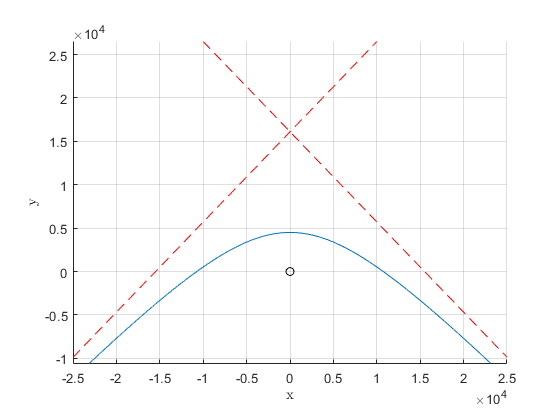


figure
plot_orbit_3d(eh,-ah,0,0+pi/2,0,[-2 2]);
plot(0,0,'ok')
x1 =[-2.5e4 1e4];
x2 =[-1e4 2.5e4];
f_asy1 = @(x) x*tan(delta/2)+ah+rph;
f_asy2 = @(x) x*tan(-delta/2)+ah+rph;

y1 = f_asy1(x1);
y2 = f_asy2(x2);
plot(x1,y1,'r--')
plot(x2,y2,'r--')
view([0 0 1])